Algunas pruebas sobre el paper de hector:Maneuvering and robutness issues in indirected displacement-consensus-based formation control.

Vamos a desarrollar algunos ejemplos para el ejemplo de cuatro agentes trantando de formar un cuadrado.

Suponemos que tenemos un grafo con las siguientes características:


$$\mathcal{G = (V,E) \\
\mathcal{V} = \{1,2,3,4\}\\
\mathcal{E} = \{(1,2),(1,3),(2,4)

$$


Construimos la matriz de incidencia,

B = [-1 -1 0; 1 0 -1; 0 1 0;0 0 1]

B =     -1    -1     0
     1     0    -1
     0     1     0
     0     0     1


Para construir la matriz laplaciana, consideramos peso $\omega_i$ Para los tres vértices de nuestro grafo. A partir de ellos la matriz laplaciana queda,


$$L = BD_{\omega}B^T$$


w1 = 2; w2 = 2; w3 = 2

w3 = 2

Dw = diag([w1 w2 w3])

Dw =      2     0     0
     0     2     0
     0     0     2


L =B*Dw*B'

L =      4    -2    -2     0
    -2     4     0    -2
    -2     0     2     0
     0    -2     0     2


Definimos ahora unas posiciones deseadas $p_i^*$ para los agentes de nuestra formación y las apilamos,

pa1 = [-1;1] ; pa2 = [-1;-1]; pa3 =[1;1]; pa4 =[1;-1]

pa4 =      1
    -1


plot(pa1(1),pa1(2),'o');hold on;plot(pa2(1),pa2(2),'o');plot(pa3(1),pa3(2),'o');plot(pa4(1),pa4(2),'o')
pa = [pa1;pa2;pa3;pa4]

pa =     -1
     1
    -1
    -1
     1
     1
     1
    -1


Calculamos $\bar{B}= B \otimes I_{2\times2}}$ y $\bar{L}=L\otimes I_{2\times 2}$

B_bar = kron(B,eye(2))

B_bar =     -1     0    -1     0     0     0
     0    -1     0    -1     0     0
     1     0     0     0    -1     0
     0     1     0     0     0    -1
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1


L_bar = kron(L,eye(2))

L_bar =      4     0    -2     0    -2     0     0     0
     0     4     0    -2     0    -2     0     0
    -2     0     4     0     0     0    -2     0
     0    -2     0     4     0     0     0    -2
    -2     0     0     0     2     0     0     0
     0    -2     0     0     0     2     0     0
     0     0    -2     0     0     0     2     0
     0     0     0    -2     0     0     0     2


Vamos a buscar una solución a


$$\dot{p} = -\bar{L}(p-p^*)$$


Para ello empezamos por considerar el problema en dos partes, Primero buscamos una solución al sistema autónomo,


$$\dot{p} = -\bar{L}p$$


y a continuación buscamos la respuesta del sistema a la entrada $-\bar{L}p^*$

Elegimos unas condiciones iniciales arbitrarias $p_0$

syms p01x p01y p02x p02y p03x p03y p04x p04y
p0 = [[0;-2];[1;1];[1;0];[0;0]]

p0 =      0
    -2
     1
     1
     1
     0
     0
     0


Si el mundo es justo, la solución al la homogénea con las condiciones iniciales impuestas debería ser $p = e^{\bar{L}t}p_0$

sys = ss(-L_bar,L_bar,eye(size(L_bar)),zeros(size(L_bar)))

sys =
 
  A = 
       x1  x2  x3  x4  x5  x6  x7  x8
   x1  -4   0   2   0   2   0   0   0
   x2   0  -4   0   2   0   2   0   0
   x3   2   0  -4   0   0   0   2   0
   x4   0   2   0  -4   0   0   0   2
   x5   2   0   0   0  -2   0   0   0
   x6   0   2   0   0   0  -2   0   0
   x7   0   0   2   0   0   0  -2   0
   x8   0   0   0   2   0   0   0  -2
 
  B = 
       u1  u2  u3  u4  u5  u6  u7  u8
   x1   4   0  -2   0  -2   0   0   0
   x2   0   4   0  -2   0  -2   0   0
   x3  -2   0   4   0   0   0  -2   0
   x4   0  -2   0   4   0   0   0  -2
   x5  -2   0   0   0   2   0   0   0
   x6   0  -2   0   0   0   2   0   0
   x7   0   0  -2   0   0   0   2   0
   x8   0   0   0  -2   0   0   0   2
 
  C = 
       x1  x2  x3  x4  x5  x6  x7  x8
   y1   1   0   0   0   0   0   0   0
   y2   0   1   0   0   0   0   0   0
   y3   0   0   1   0   0   0   0   0
   y4   0   0   0   1   0   0   0   0
   y5   0   0   0   0   1   0   0   0
   y6   0   0   0   0   0   1   0   0
   y7   0   0   0


[x,t]= initial(sys,p0)

x =          0   -2.0000    1.0000    1.0000    1.0000         0         0         0
    0.0515   -1.8708    0.9485    0.8970    0.9741   -0.0515    0.0259    0.0252
    0.0983   -1.7522    0.9017    0.8033    0.9502   -0.0983    0.0498    0.0471
    0.1409   -1.6434    0.8591    0.7181    0.9281   -0.1408    0.0719    0.0661
    0.1797   -1.5435    0.8203    0.6405    0.9076   -0.1795    0.0924    0.0824
    0.2149   -1.4517    0.7851    0.5699    0.8887   -0.2145    0.1113    0.0963
    0.2469   -1.3674    0.7531    0.5057    0.8712   -0.2463    0.1288    0.1080
    0.2760   -1.2900    0.7240    0.4472    0.8550   -0.2751    0.1450    0.1178
    0.3024   -1.2188    0.6976    0.3940    0.8400   -0.3012    0.1600    0.1259
    0.3264   -1.1533    0.6736    0.3456    0.8260   -0.3247    0.1740    0.1324


t =          0
    0.0135
    0.0270
    0.0405
    0.0540
    0.0674
    0.0809
    0.0944
    0.1079
    0.1214


plot(x(:,1),x(:,2))
hold on
plot(x(:,3),x(:,4))
plot(x(:,5),x(:,6))
plot(x(:,7),x(:,8))
t = 0:0.01:30

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


u = kron(ones(size(t)),pa)'

u =     -1     1    -1    -1     1     1     1    -1
    -1     1    -1    -1     1     1     1    -1
    -1     1    -1    -1     1     1     1    -1
    -1     1    -1    -1     1     1     1    -1
    -1     1    -1    -1     1     1     1    -1
    -1     1    -1    -1     1     1     1    -1
    -1     1    -1    -1     1     1     1    -1
    -1     1    -1    -1     1     1     1    -1
    -1     1    -1    -1     1     1     1    -1
    -1     1    -1    -1     1     1     1    -1



[x,t] = lsim(sys,u,t,p0)

x =    -0.0000   -2.0000    1.0000    1.0000    1.0000   -0.0000         0         0
   -0.0006   -1.8643    0.9222    0.8839    1.0198   -0.0382    0.0586    0.0186
   -0.0022   -1.7368    0.8485    0.7753    1.0392   -0.0731    0.1146    0.0347
   -0.0049   -1.6171    0.7787    0.6736    1.0581   -0.1049    0.1680    0.0483
   -0.0083   -1.5046    0.7126    0.5785    1.0767   -0.1337    0.2191    0.0597
   -0.0126   -1.3988    0.6501    0.4894    1.0947   -0.1598    0.2678    0.0691
   -0.0175   -1.2993    0.5908    0.4060    1.1124   -0.1833    0.3144    0.0766
   -0.0230   -1.2058    0.5346    0.3279    1.1295   -0.2045    0.3589    0.0823
   -0.0291   -1.1178    0.4814    0.2547    1.1463   -0.2234    0.4014    0.0865
   -0.0356   -1.0350    0.4309    0.1862    1.1625   -0.2403    0.4421    0.0891


t =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


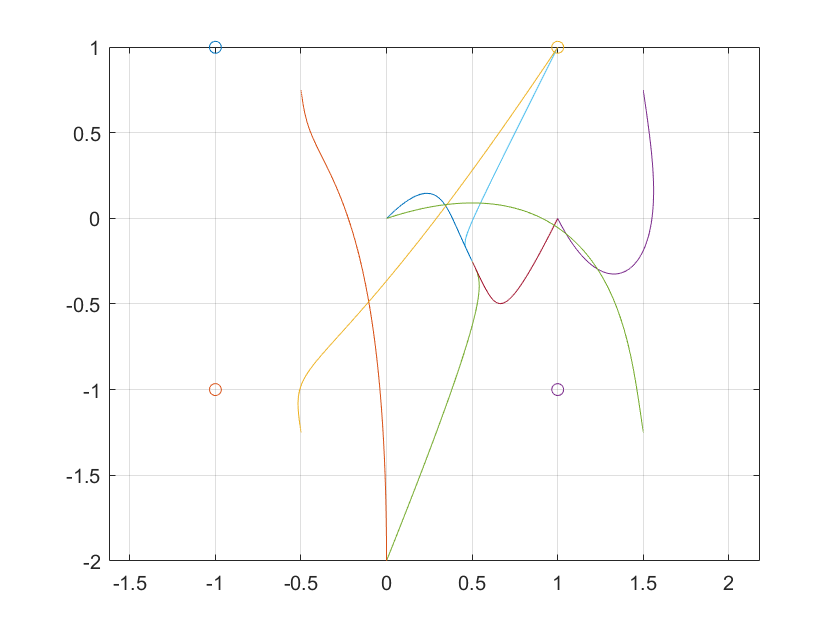

plot(x(:,1),x(:,2))
hold on
plot(x(:,3),x(:,4))
plot(x(:,5),x(:,6))
plot(x(:,7),x(:,8))
axis 'equal'
grid

Pero qué pasa si uno de los agentes tiene otro plan¿?